# 实验二　MATLAB绘图

## 第2章

### 2. 用plot、fplot绘制函数$y=\mathrm{cos}\left(\mathrm{tan}\left(\pi x\right)\right)$的图形。

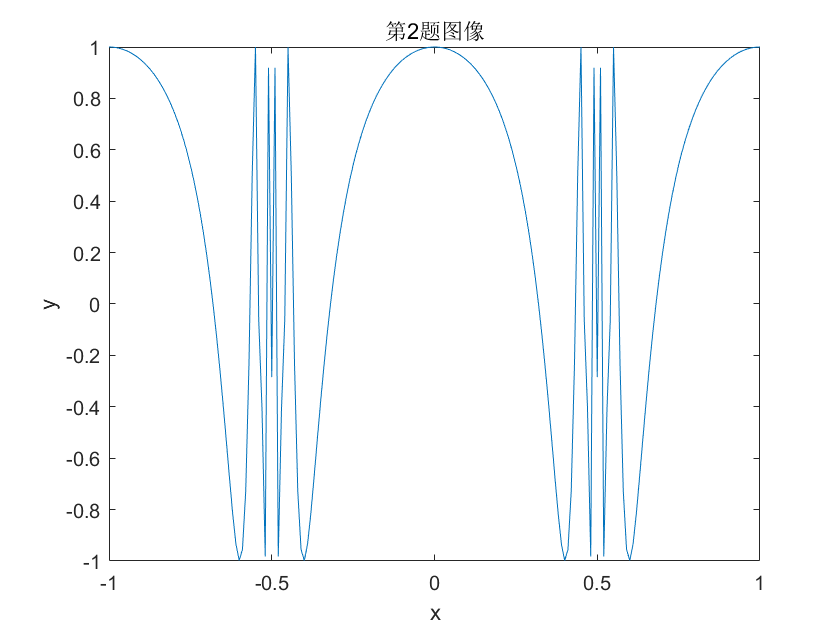

x = -1 : 0.01 : 1;
y = cos(tan(pi .* x));
plot(x, y);
title('第2题图像');
xlabel('x');
ylabel('y');

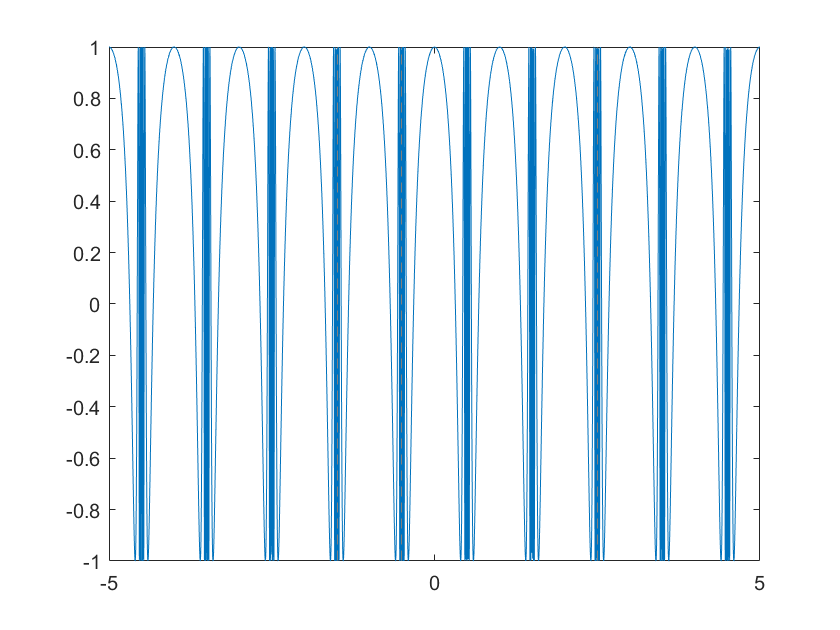

syms x y
fplot(cos(tan(pi * x)))

### 3. 用ezplot绘制函数$y=e^{\mathrm{xy}} -\mathrm{sin}\left(x+y\right)=0$在$\left\lbrack -3,3\right\rbrack$上的图形。

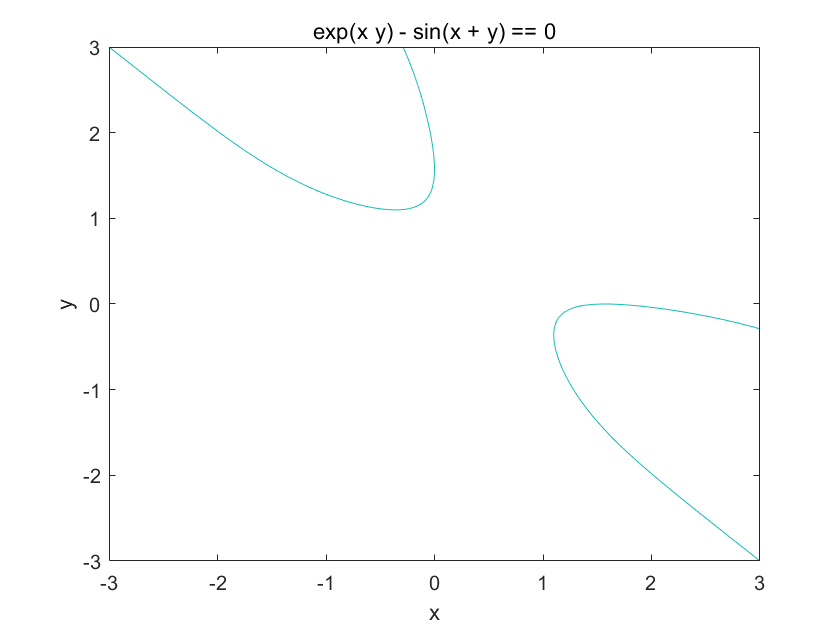

%% 【警告】
% MATLAB R2019a已经不建议使用ezplot()进行绘图
% 若函数形式为单变量显函数，则使用fplot()
% 否则，请使用fimplicit()
% ezplot()将在后续版本被弃用（到R2019a仍可被调用）
ezplot(exp(x*y)-sin(x+y)==0, [-3, 3]);

### 4. 用ezplot绘制摆线$\left\lbrace \begin{array}{c}
x=a\left(t-\mathrm{sin}\left(t\right)\right)\\
y=a\left(1-\mathrm{cos}\left(t\right)\right)
\end{array}\right.$，$t\in \left\lbrack 0,2\pi \right\rbrack$的图形。

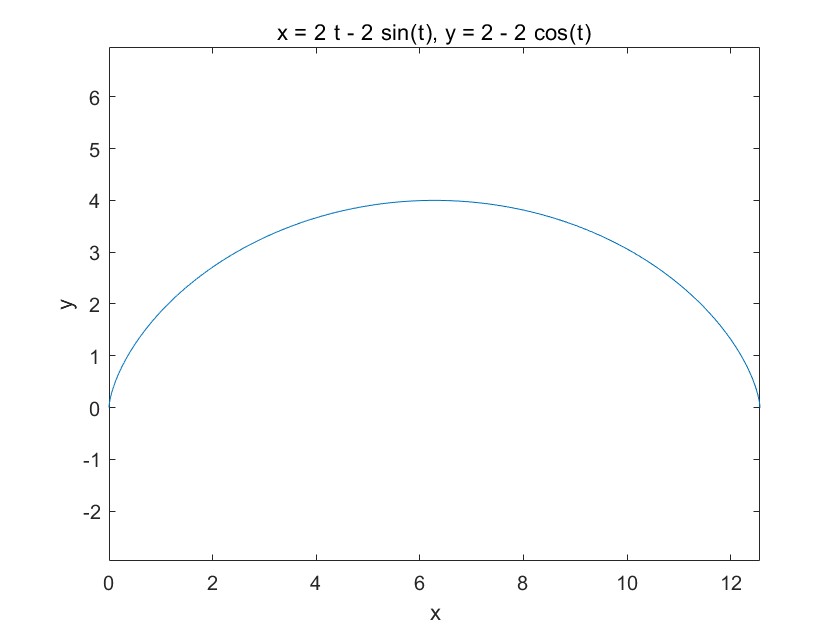

syms x y t a
% 此处插入了一个数值滑块控件，可以自由设置a的具体数值
a = 2;
ezplot(a*(t-sin(t)), a*(1-cos(t)));

### 5. 用surf、mesh绘制曲面$z=2x^2 +y^2$。

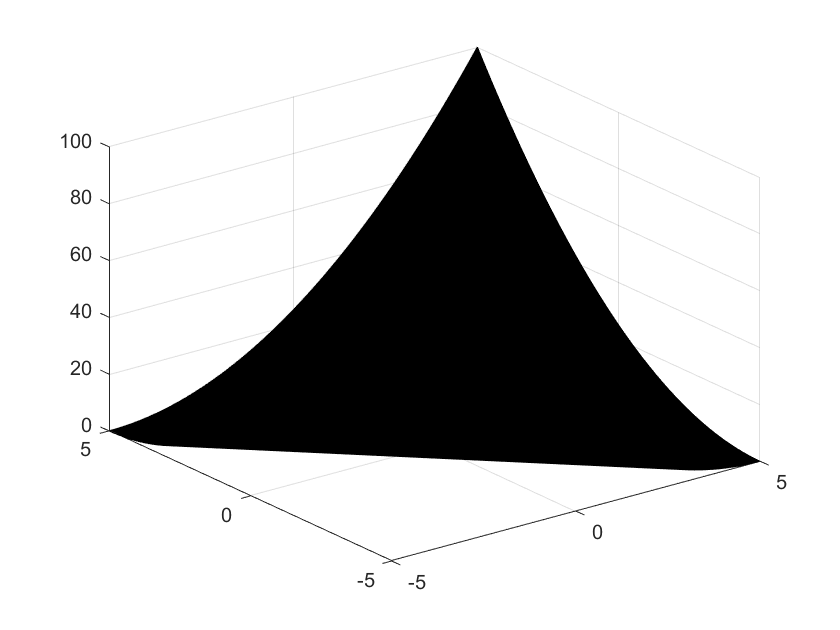

x = -5 : 0.01 : 5;
y = -5 : 0.1 : 5;
[X, Y] = meshgrid(x, y);
Z = (X + Y) .^ 2;
surf(X, Y, Z);

### 6. 用polar绘制阿基米德螺线$r=a\theta$和三叶玫瑰线$r=\mathrm{acos}\left(3\theta \right)$。

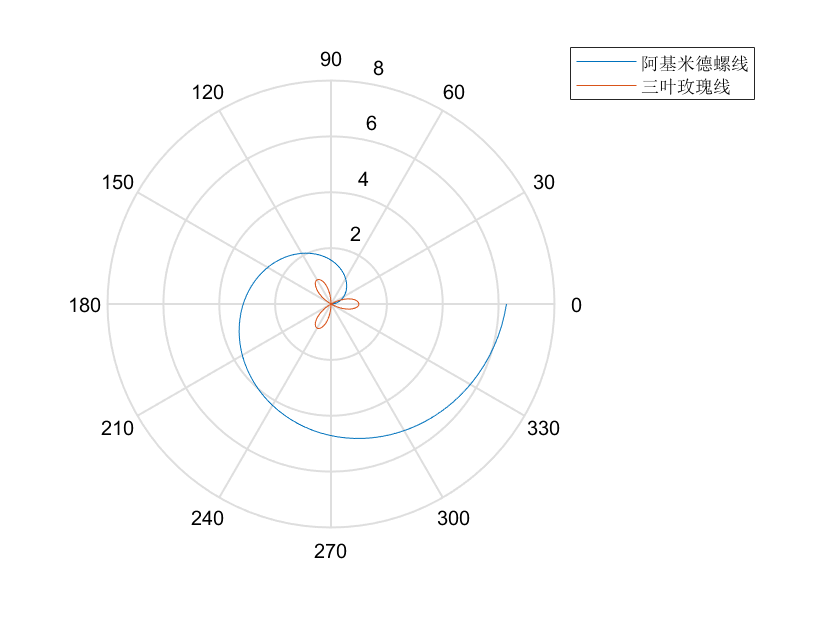

theta = linspace(0, 2 * pi);
a = 1;
rho = [a .* theta; a .* cos(3 .* theta)];
% MATLAB R2019a强烈阻止使用polar，
% 并建议使用polarplot()代替
polar(theta, rho(1, :));
polar(theta, rho(2, :));
legend('阿基米德螺线', '三叶玫瑰线', "Location", "bestoutside");

### 7. 在同一平面的两个窗口中分别画出心形线和马鞍面，要求：

#### 　　（1）在图形上加格栅、图例和标注；

#### 　　（2）定制坐标；

#### 　　（3）以不同的角度观察马鞍面。

　　心形线采用平面极坐标形式定义，即$\rho =a\left(1-\mathrm{sin}\left(\theta \right)\right)$。马鞍面采用空间直角坐标系定义，即$z=\mathit{xy}$

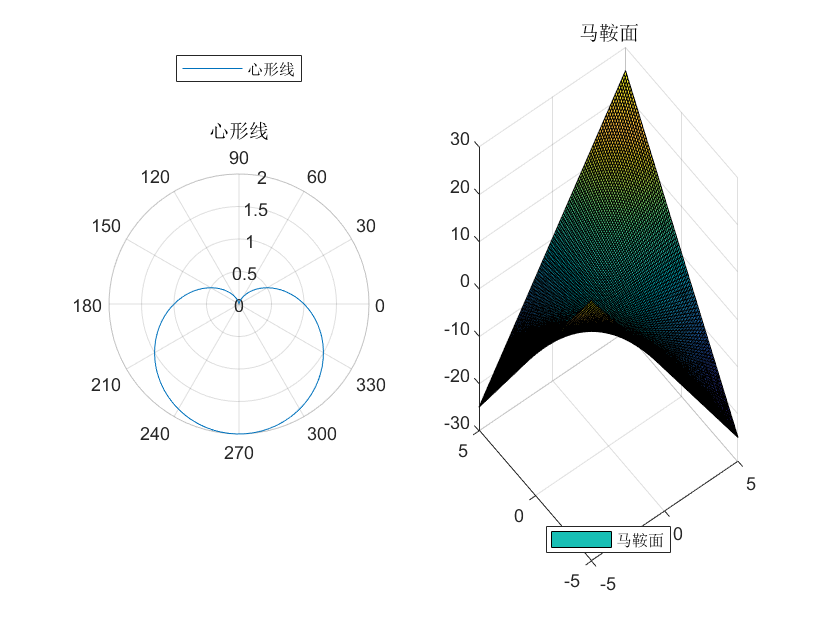

subplot(1, 2, 1);
a = 1;
theta = linspace(0, 2 * pi);
rho = a .* (1 - sin(theta));
polarplot(theta, rho);
legend('心形线', "Location", "best");
title('心形线');
subplot(1, 2, 2);
x = linspace(-5, 5);
y = linspace(-5, 5);
[X, Y] = meshgrid(x, y);
Z = X .* Y;
surf(X, Y, Z);
legend('马鞍面', "Location","best");
title('马鞍面');